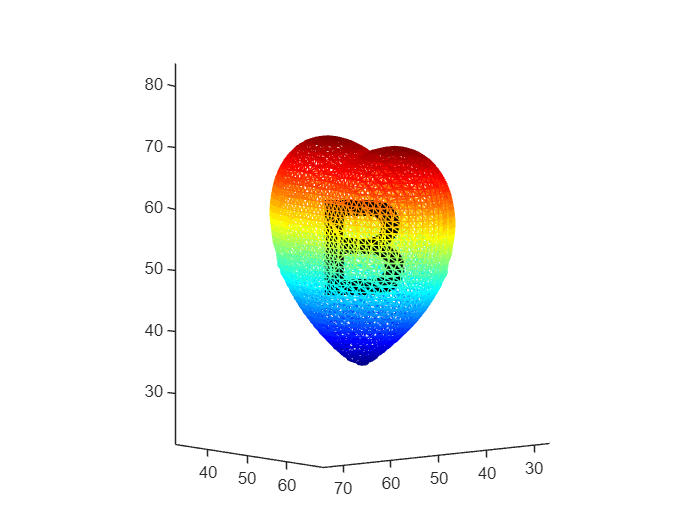

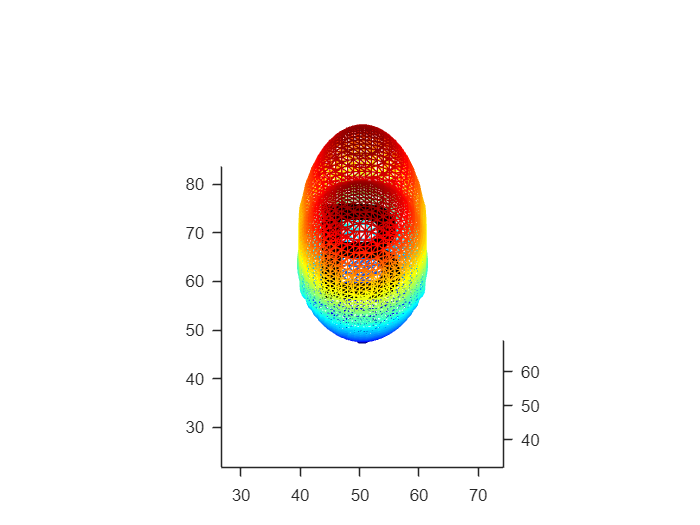

n = 100;
x = linspace(-3, 3, n);
y = linspace(-3, 3, n);
z = linspace(-3, 3, n);
[X, Y, Z] = ndgrid(x, y, z);
F = (((-X.^2) .* (Z.^3) - (9/80) .* (Y.^2) .* (Z.^3)) + ((X.^2) + (9/4) .* (Y.^2) + (Z.^2) - 1).^3);

fig = figure;
hold on;
axis equal;
colormap('jet');

for angle = 0:1:360
    clf;

    p = patch(isosurface(F, 0));
    set(p, 'FaceColor', 'none', 'EdgeColor', 'interp');
    p.FaceVertexCData = p.Vertices(:,3);
    p.EdgeColor = 'flat';

    lighting phong;
    axis equal;

    view([angle 35]);
    
    text(50, 50, 54, 'B', 'FontSize', 80, 'FontWeight', 'bold', 'Color', 'k', 'HorizontalAlignment', 'center');

    drawnow;
end